ФЕДЕРАЛЬНОЕ АГЕНТСТВО ЖЕЛЕЗНОДОРОЖНОГО ТРАНСПОРТА

Федеральное государственное бюджетное образовательное

учреждение высшего образования 

"Петербургский государственный университет

путей сообщения ИМПЕРАТОРА АЛЕКСАНДРА I"

Кафедра «Электрическая тяга»

Лабораторная работа №3 

«Исследование трехфазного мостового управляемого выпрямителя»

Вариант №1

Выполнили студенты группы ПС – 005:

Ульянчик Р.Н., Никитин Д.Г., Астафьев И.М.

Проверил: 

Викулов И.П.

Санкт-Петербург

2024

Цель работы: Исследование методом компьютерного моделирования трехфазного двухполупериодного (мостового) управляемого выпрямителя при работе на активно-индуктивную нагрузку.

Принципиальная схема САУТ приведена на рисунке 1.

Исходные данные

run('Skript_vyvoda_iz_txt.mlx');
% Source.VoltageRMS = 150;
% frequency = 50;
% Tran.Inductance = 0.0002;
% Tran.Resistance = 0.001;
% Thyr.ForwVolt = 0.8;
% Thyr.ResistanceRon = 0.001;
Source = table(VoltageRMS);
Source.VoltageAmplitude = Source.VoltageRMS * sqrt(2);
Tran = table(Inductance, Resistance);
Thyr = table(ForwVolt, ResistanceRon);

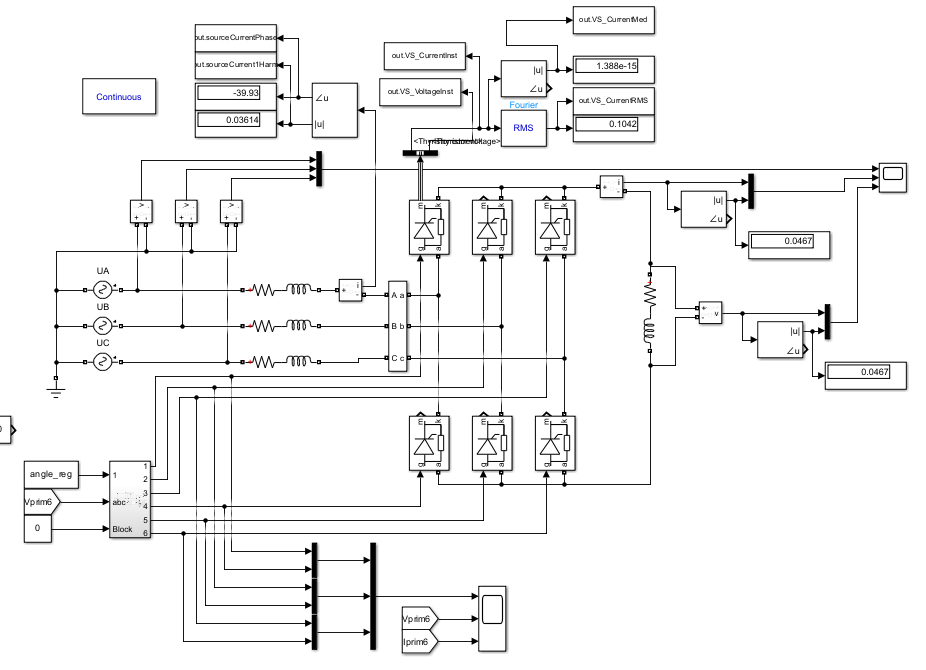

Рисунок 1 - Модель трехфазного управляемого выпрямителя

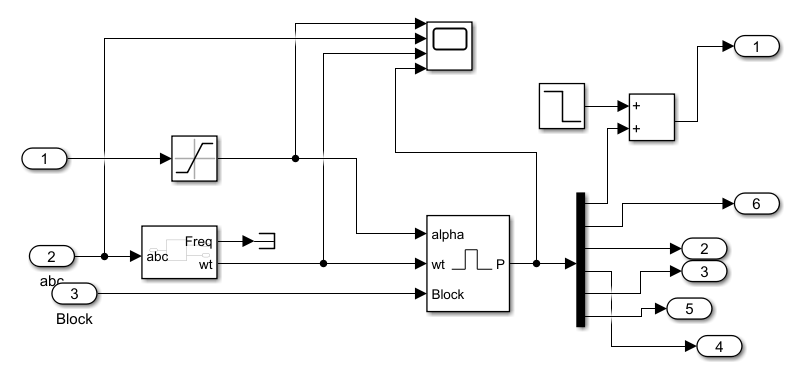

Рисунок 2 – Блок управления трехфазным управляемым выпрямителем

I_n = [];
U_n = [];
I_1max = [];
Phi_1max = [];
I_VSsr = [];
I_VSD = [];
U_VSmax = [];
I_VSmax = [];
S_1 = [];
P_1 = [];
P_n = [];
P_T = [];
Angle_tbl = [];
Resistance_tbl = [];
resist_tbl = [];
angle_raschet = [];
angle = [0, 40, 60];

Производим моделирование 

for i = 1:3
    angle_reg = angle(i);
    for resist = [1, 2, 4, 10]
        load.Res = resist;
        resist_tbl(end+1) = load.Res;
        load.Ind = load.Res * 2 / frequency;
        sim("lr3.slx");
        Angle_tbl(end+1) = angle_reg;
        I_n(end+1) = ans.ScopeUtranInUn.signals(2).values(end, 2);
        U_n(end+1) = ans.ScopeUtranInUn.signals(3).values(end, 2);
        I_1max(end+1) = ans.sourceCurrent1Harm.Data(end);
        Phi_1max(end+1) = ans.sourceCurrentPhase.Data(end);
        I_VSD(end+1) = max(ans.VS_CurrentMed.Data);
        I_VSsr(end+1) = max(ans.VS_CurrentRMS.Data);
        U_VSmax(end+1) = max(ans.VS_VoltageInst.Data);
        I_VSmax(end+1) = max(ans.VS_CurrentInst.Data);
        S_1(end+1) = Source.VoltageAmplitude * I_1max(end) / 2;
        P_1(end+1) = S_1(end) * cosd(Phi_1max(end));
        P_n(end+1) = U_n(end) * I_n(end);
        P_T(end+1) = Thyr.ForwVolt*I_VSsr(end) + Thyr.ResistanceRon*I_VSD(end)^2;
    end
end

Произодим расчёты

Зависимость выпрямленного напряжения цепи возбуждения ТЭД от угла фазового регулирования определяется следующей формулой, В: 


$$u_в \left(\alpha {\;}_p \right)=1,35\cdot U_{\mathrm{тв}} \cos \alpha -\left(R_э +R_T \right)i_в -\Delta U_{\mathrm{ув}}$$


Полная и активная мощность по первой гармонике, потребляемая выпрямителем из сети, рассчитываются по выражениям, ВА:


$$S_1 \left(1\right)=\frac{\left(3U_{1\max } I_1 {\left(1\right)}_{\max } \right)}{2}$$



$$P_1 \left(1\right)=\frac{\left(3U_{1\max } I_1 {\left(1\right)}_{\max } \cos \phi_1 \right)}{2}$$


Мощность в нагрузке определяется по выражению, Вт:


$$P_н =U_н I_н$$


Потери в тиристоре УВ рассчитываются по выражению, Вт:


$$P_T =U_f I_{\mathrm{VScp}} +I_{\mathrm{VSд}}^2 R_{\mathrm{on}}$$


Таблица 1 – Таблица измерений и вычислений

T = table(Angle_tbl.',resist_tbl.',I_n.', U_n.',I_1max.',Phi_1max.',I_VSsr.',I_VSD.',I_VSmax.', U_VSmax.', ...
    S_1.', P_T.', P_1.', P_n.');
T.Properties.VariableNames = ["\alpha", "R", "Iн", "Uн", "I(1)max", "\phi","Ivt_ср","Ivt_d","Ivsmax", "U_Vsmax", ...
    'S(1)', 'Pт', 'P(1)', 'Pн'];
disp(T);

    \alpha    R       Iн        Uн      I(1)max     \phi      Ivt_ср    Ivt_d     Ivsmax    U_Vsmax     S(1)       Pт       P(1)        Pн    
    ______    __    ______    ______    _______    _______    ______    ______    ______    _______    ______    ______    ______    _________

       0       1     324.8    324.82    356.95     -20.087    182.69    216.93    325.24    51.143      37860    193.21     35557    1.055e+05
       0       2    168.29     336.6     185.4     -14.627    95.478    112.57    168.49    28

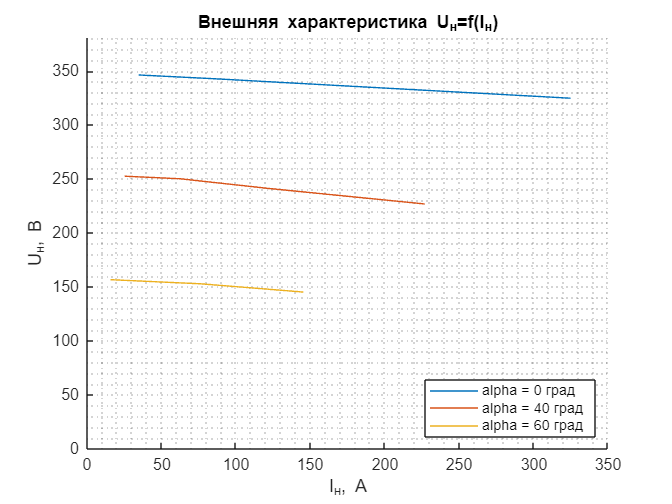

plotres = strings(0,0);
for i=1:4
    plotres(i) = sprintf('R = %d Ом', resist_tbl(i));
end
plotangle = strings(0,0);
for i=1:3
    plotangle(i) = sprintf('alpha = %d град', angle(i));
end
makeplot_lr32(I_n, U_n, 'I_н, А', 'U_н, В', plotangle);
title("Внешняя характеристика U_н=f(I_н)");
saveas(gcf, 'внеш_хар-ка.png');

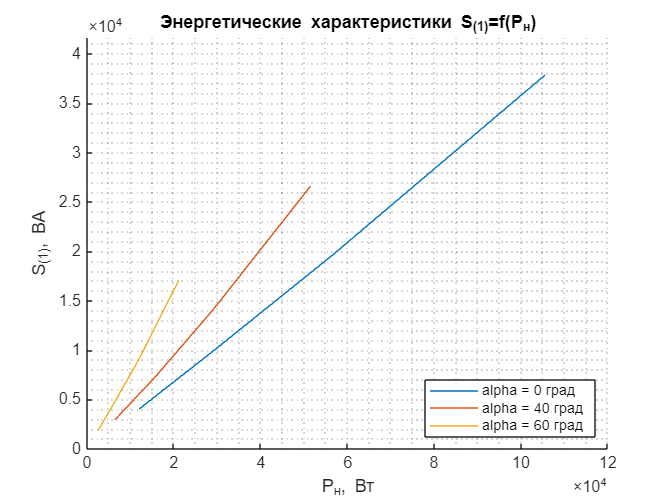

makeplot_lr32(P_n, S_1, 'P_н, Вт', 'S_{(1)}, ВА', plotangle);
title("Энергетические характеристики S_{(1)}=f(P_н)");
saveas(gcf, 'эн_хар-ка1.png');

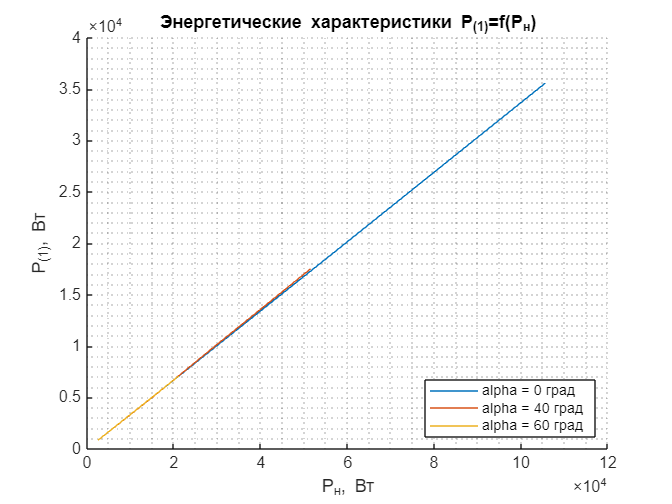

makeplot_lr32(P_n, P_1, 'P_н, Вт', 'P_{(1)}, Вт', plotangle);
title("Энергетические характеристики P_{(1)}=f(P_н)");
saveas(gcf, 'эн_хар-ка2.png');

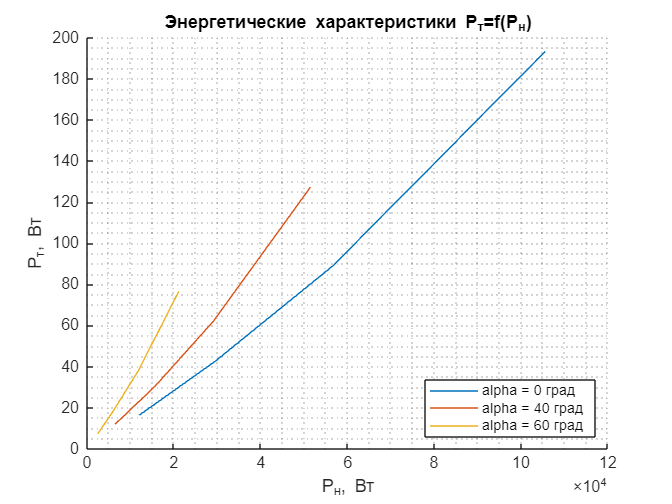

makeplot_lr32(P_n, P_T, 'P_н, Вт', 'P_т, Вт', plotangle);
title("Энергетические характеристики P_т=f(P_н)");
saveas(gcf, 'эн_хар3.png');

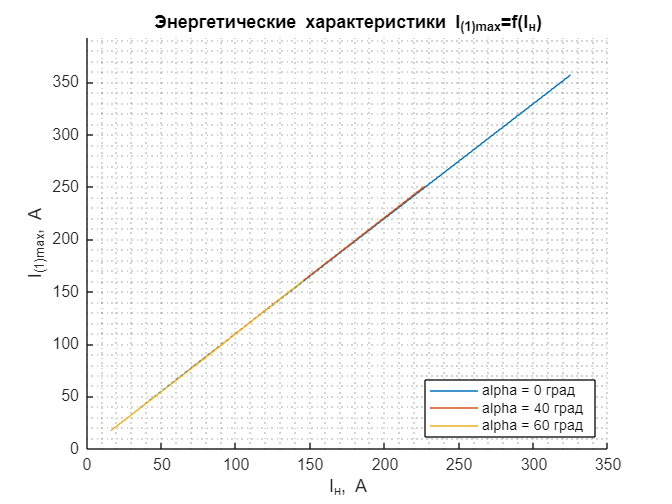

makeplot_lr32(I_n, I_1max, 'I_н, А', 'I_{(1)max}, А', plotangle);
title("Энергетические характеристики I_{(1)max}=f(I_н)");
saveas(gcf, 'эн_хар-ка4.png');

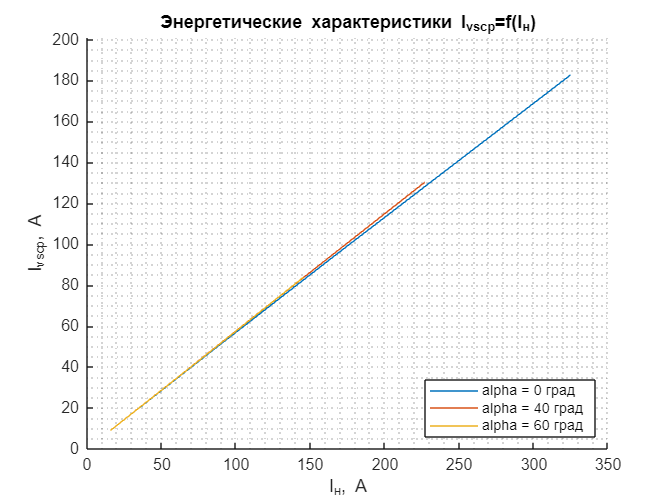

makeplot_lr32(I_n, I_VSsr, 'I_н, А', 'I_{vsср}, А', plotangle);
title("Энергетические характеристики I_{vsср}=f(I_н)");
saveas(gcf, 'эн_хар-ка5.png');

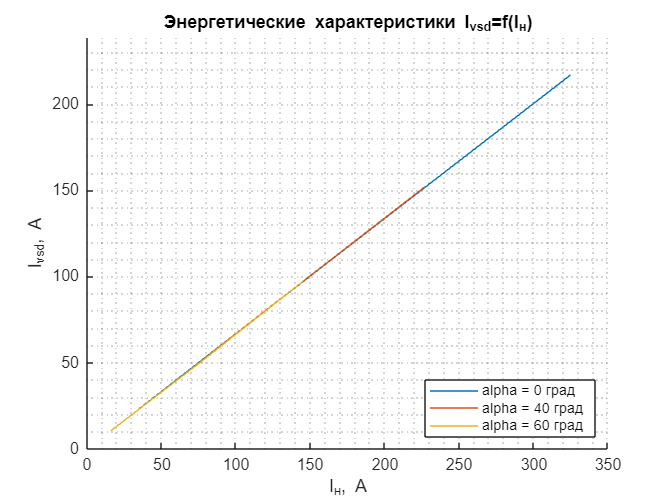

makeplot_lr32(I_n, I_VSD, 'I_н, А', 'I_{vsd}, А', plotangle);
title("Энергетические характеристики I_{vsd}=f(I_н)");
saveas(gcf, 'эн_хар-ка6.png');

load.Res = 1;
load.Ind = load.Res * 2 / frequency;
U_nr = [];
U_nr2 = [];
U_n2 = [];
Angle_tbl2 = [];
for angle_reg = 0:20:120
    sim("lr3.slx");
    Angle_tbl2(end+1) = angle_reg;
    U_n2(end+1) = ans.ScopeUtranInUn.signals(3).values(end, 2);
    I_v = ans.ScopeUtranInUn.signals(2).values(end, 2);
    U_tv = Source.VoltageRMS * sqrt(3);
    delta_Uf = 2*(Thyr.ForwVolt+Thyr.ResistanceRon*max(ans.VS_CurrentMed.Data));
    U_nr(end+1) = 1.35*U_tv*cosd(angle_reg) - ((2*pi*frequency*Tran.Inductance+Tran.Resistance))*I_v - delta_Uf;
end

Таблица 2 – Измерение и расчет регулировочной характеристики

T1 = table(Angle_tbl2.',U_n2.', U_nr.');
T1.Properties.VariableNames = ["\alpha","Un","Uнр"];
disp(T1);

    \alpha       Un         Uнр  
    ______    ________    _______

       0        324.82     327.97
      20         290.8     309.04
      40        226.82      252.3
      60        145.23     164.31
      80        39.966     56.702
     100      0.083712    -62.539
     120      0.046701    -176.98



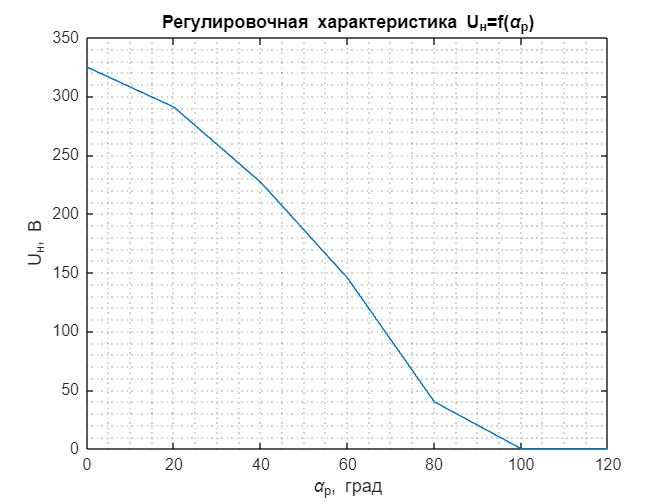

figure
plot(Angle_tbl2,U_n2);
grid('minor');
xlabel("\alpha_р, град");
ylabel("U_н, В");
title("Регулировочная характеристика U_н=f(\alpha_р)");
saveas(gcf, 'Регулировочная характеристика.png')

writetable(T, 'Таблица измерений и вычислений.xlsx');
writetable(T1, 'Таблица измерений и вычислений.xlsx', 'Sheet', 'Sheet2');

Вывод

Создана схема работы в simulink, были рассчитаны основные характеристики. Построены внешние, регулировочные, энергетические характеристики. Добавлен вывод графиков и сводных таблиц в png и xlsx соответственно.